Vezmeme si BGD s adaptivním moomentem a doděláme to něj tzv. Lasso Regression. Jedná se vlastně o utlumení koeficientů s nízkou hodnotou. Díky tomu získáme sice o něco nepřesnější model, ale na druhou stranu ho výrazně zjednodušíme. To znamená že výpočet bude rychlejší, takže tento způsob je vhodný např. pro real time aplikace.

Testovací data budou v podobě zašuměnné:

#### 
$$y\left(x\right)={3x}^3$$
 

Bázová funkce našeho modelu:

#### 
$$y\left(x\right)={w_5 x}^4 +{w_4 x}^3 +{w_3 x}^2 +w_2 x+w_1$$
 

Přebytečné koeficienty budou dohánět šum v původnách datech a výsledný model tak bude přesnější, ale taky jeho výpočet bude náročnější, něž kdybychom měli bázovou funkci pouze:

#### 
$$y\left(x\right)={w_1 x}^3$$
 

Nagenerujeme data pomocí funkce. V tomto případě se jedná o fnunkci:

#### 
$$y\left(x\right)={3x}^3$$
 

func = @(x) (3.*x.^3);              % funkce pro nagenerování dat
from = -1.5;                        % rozsah pro od ...
to = 1.5;                           % ... do pro nagenerování dat
N =  20;                            % počet vzorků
x = from:((to-from)/(N-1)):to;      % vzorkovací čas
y = awgn(func(x),20);               % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)

Koeficient $\alpha$ je klasicky koeficient učení a koeficient $\tau$ zase maximální přípustnou chybu v modelu.

alpha = 1e-3;   % míra učení 
tau = 1e-3;     % maximální možná chyba pro ukončení výpočtu

Koeficient $\lambda$ zase vyjadřuje, jak moc budou malé koeficienty tlumené. Pokud bude $\lambda$ hodně velké, tak utlumí všechny koeficienty a aproximace bude velmi špatná. Pokud bude naopak příliš malé, tak se v řešeení nijak neprojeví. Pokud ale nastavíme tento koeficient na rozumnou hodnotu, tak můžeme docílit stále kvalitně aproximujícího modelu, který ale bude mít určité koeficienty téměř nulové. To znamená, že je můžeme z modelu vypusitit a tím zrychlit následný výpočet.

lambda = 1e-3; % koeficient regularizace pro malé koeficienty.

Naše bázová funkce má tedy podobu:

#### 
$$y\left(x\right)={w_5 x}^4 +{w_4 x}^3 +{w_3 x}^2 +w_2 x+w_1$$
 

Následující kód generuje právě tuto funkci vytvoří

M = 4;              % řád polynomu
syms w_sym [1,M+1];

y_sym = sym(0);
syms x_sym;
for i = 1:M+1                                             % vypočítej přes daný řád polynomu
    y_sym = y_sym + (w_sym(i).*(x_sym.^(i-1)));    % podle rovnice polynomu (x^j*w_j)
end

Aby byl vliv Lasso regularizace patrný, tak vypočteme jeden a ten samý příklad několikrát pro různé hodnoty regularizace a porovnáme je mezi sebou. Z toho důvodu si předpřipravíme vše co je možné, aby následný výpočet trval co nejkratší dobu. Takže zde je připraven výpočet pro ztrátovou funkci a koeficienty pro výpočet adaptivního momentu.

model = subs(y_sym,x_sym,x);
epsilon = 10e-8;
beta1 = 0.9;
beta2 = 0.999;

Tato proměná počítá kolikrát byl výpočet pro různé hodnoty regularizace proveden.

counter = 1;

Tato proměná zase vypovídá o tom, jaké hodnoty regularizace budou počítány

range = -3:0.5:2

range =    -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000


A nyní už výpočet. Ten začíná výjádřením ztrátové funkce podle vzorce metody nejmenších čtverců s Lasso regularizací:

#### 
$$E=\left(\sum_{n_0 }^N {\left(y_{\textrm{naměřené}} -y_{\textrm{aproximovaé}} \right)}^2 \right)+\lambda \left(|w_1 |+|w_2 |+|w_3 |+\ldotp \ldotp \ldotp +|w_m |\right)$$


kde vzorec metody nejmenších čtverců je klasický, ale je zde připočítávána absolutní hodnota všech koeficientů přenásobená koeficientem $\lambda$.  Následuje už pouze výpočet gradientu, nastavení počátečních koeficientů a samotný výpočet za pomocí ADAMa.

for j = range
   
    lambda = (0.1^-j);
    lasso = lambda.*(sum(abs(w_sym)));
    E_sym = sum(((y-model).^2) + lasso);

    grad_E_sym = gradient(E_sym,w_sym);
    m = 0;
    v = 0;

    w = (ones(M+1,1));

    for i = 1:5000 
   
        grad_E = double(subs(grad_E_sym,w_sym,w'));
    
        m = beta1.*m+(1-beta1).*grad_E;
        v = beta2.*v+(1-beta2).*grad_E.^2;
 
        mm = m./(1-beta1^i);
        vv = v./(1-beta2^i);
       
        if (abs(max(grad_E)) < tau)
            iter = i;
            break;
        end
     
        w = w - ((alpha.*mm)./(sqrt(vv)+epsilon));
    
    end

Po nalezení koeficietů jsou koeficienty vypsány, a uloženy do matice pro pozdější vykreslení. 

    w
    W(:,counter) = w;

Zde jsou vpočteny body podle aproximace, a to z důvodu, abychom mohli vypočíst pomocí metody nejměnších čtverců jejich odchylku od naměřených dat. Tyto odchylky ukládám do matice mse (mean square error) pro pozdější vykreslení.

    y_model = double(subs(subs(y_sym,w_sym,w'),x_sym,x));
    mse(counter) = Least_squares_method(y,y_model);

Následuje vykreslení naměřených dat.

    plot(x,y,"ro");
    hold on;

Vykreslení aproximace vypočteným modelem.

    plot(x,y_model,"b-");
    hold off;
    drawnow;
    

Je inkrementován čítač a výpočet běží pro další hodnotu $\lambda$.

w =    -0.0635
    0.5419
   -0.0087
    2.6615
    0.0117


w =    -0.0634
    0.5415
   -0.0082
    2.6616
    0.0114


w =    -0.0633
    0.5410
   -0.0076
    2.6618
    0.0110


w =    -0.0631
    0.5404
   -0.0068
    2.6620
    0.0105


w =    -0.0629
    0.5397
   -0.0058
    2.6623
    0.0099


w =    -0.0626
    0.5388
   -0.0046
    2.6627
    0.0092


w =    -0.0622
    0.5376
   -0.0030
    2.6632
    0.0082


w =    -0.0618
    0.5361
   -0.0011
    2.6638
    0.0070


w =    -0.0609
    0.5343
   -0.0000
    2.6645
    0.0058


w =    -0.0592
    0.5319
    0.0000
    2.6655
    0.0051


w =    -0.0572
    0.5290
    0.0000
    2.6666
    0.0043


w =    -0.0546
    0.5253
   -0.0000
    2.6681
    0.0032


w =    -0.0513
    0.5206
    0.0000
    2.6700
    0.0019


w =    -0.0474
    0.5147
   -0.0000
    2.6723
    0.0002


w =    -0.0446
    0.5073
   -0.0000
    2.6753
    0.0000


w =    -0.0413
    0.4979
   -0.0000
    2.6790
   -0.0000


w =    -0.0372
    0.4861
   -0.0000
    2.6837
    0.0000


w =    -0.0321
    0.4713
   -0.0000
    2.6897
    0.0000


w =    -0.0256
    0.4526
   -0.0000
    2.6972
   -0.0000


w =    -0.0174
    0.4290
   -0.0000
    2.7066
   -0.0000


w =    -0.0071
    0.3993
   -0.0000
    2.7186
   -0.0000


w =    -0.0000
    0.3618
    0.0000
    2.7336
   -0.0000


w =    -0.0000
    0.3144
   -0.0000
    2.7527
   -0.0000


w =     0.0000
    0.2546
   -0.0000
    2.7768
    0.0000


w =    -0.0001
    0.1790
   -0.0000
    2.8073
   -0.0000


w =     0.0000
    0.0834
   -0.0001
    2.8459
   -0.0000


w =    -0.0001
    0.0003
   -0.0001
    2.8881
   -0.0000


w =     0.0001
   -0.0001
    0.0001
    2.8727
   -0.0000


w =    -0.0001
    0.0006
   -0.0001
    2.8431
   -0.0001


w =    -0.0001
    0.0001
   -0.0000
    2.8056
   -0.0001


w =    -0.0000
   -0.0001
   -0.0001
    2.7584
    0.0001


w =     0.0000
    0.0000
    0.0000
    2.6989
   -0.0001


w =     0.0001
    0.0002
   -0.0001
    2.6240
    0.0001


w =     0.0000
    0.0002
    0.0001
    2.5296
    0.0000


w =    -0.0001
    0.0001
    0.0004
    2.4109
   -0.0000


w =    -0.0002
    0.0001
   -0.0002
    2.2613
   -0.0002


w =    -0.0001
    0.0001
    0.0000
    2.0731
    0.0001


w =     0.0002
    0.0002
    0.0001
    1.8362
    0.0001


w =    -0.0001
   -0.0000
   -0.0000
    1.5380
   -0.0001


w =    -0.0001
    0.0002
   -0.0002
    1.1622
    0.0003


w =     0.0001
   -0.0001
   -0.0002
    0.6896
    0.0000


w =    -0.0000
   -0.0001
   -0.0000
    0.0945
   -0.0000


w = 	1.0e+-3 *

    0.0709
    0.2698
    0.1156
    0.4216
    0.1458


w = 	1.0e+-3 *

   -0.0570
    0.2613
   -0.0865
    0.0248
   -0.1562


w = 	1.0e+-3 *

    0.0179
    0.0406
    0.0399
    0.2851
    0.1444


w = 	1.0e+-3 *

    0.3364
    0.2569
    0.1524
   -0.0839
   -0.0026


w = 	1.0e+-3 *

   -0.0767
    0.1291
    0.0195
    0.0854
    0.1539


w = 	1.0e+-3 *

   -0.0812
   -0.0722
    0.1519
    0.2225
   -0.0442


w = 	1.0e+-3 *

    0.1100
    0.0114
    0.0556
    0.0079
    0.1062


w = 5×1
	1.0e+-3 *

    0.0751
    0.1086
   -0.1028
    0.3506
    0.0020


w = 5×1
	1.0e+-3 *

   -0.0900
   -0.3019
   -0.0372
    0.2826
   -0.0101


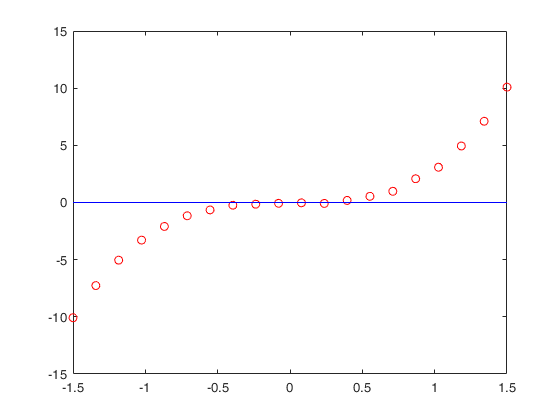

    counter = counter + 1; 
end

Vypočtené výsledky můžeme zobrazit takto: 

První gaf ukazuje, že čím větší Lasso regulatizaci jsme zavedli, tím víc nám utlumovala i koeficienty (v našem případě jen koeficient $w_4$), které utlumeny být neměly. V důsledku toho je pro velkou regularizaci model výrazně hoorší. Naoopak pro malé hodnoty $\lambda$ je vidět, že nám výslednou hodnotu ztrátové funkce spočtenou metodou nejmenších čtverců už prakticky nemění. 

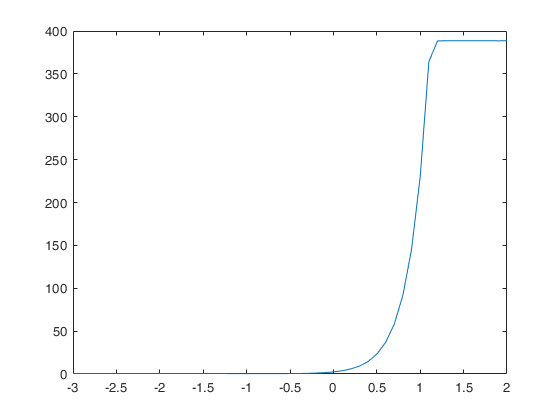

plot(range,mse);
hold off;

Druhý graf zobrazuje jakou měli koeficienty hodnotu napříč všemi výpočty. Lze vidět, že pro malé hodnoty $\lambda$ byli všechny koeficienty nenulové, ale ty nejmenší byli následně tlumeny až do zanedbatelné velikosti. Zároveň je ale vidět, že pro velké $\lambda$ nám regularizace utlumila všechny koeficienty, čili i koeficient $w_4$, který byl pro aproximaci stěžejní. 

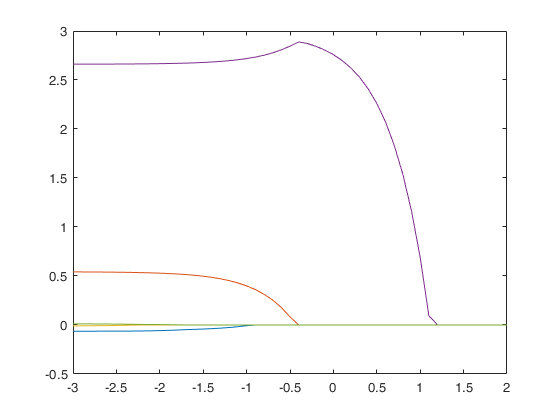

for i = 1:M+1

    plot(range,W(i,:));
    hold on
end
hold off

Nakonec si vykreslíme Paretovo optimum závislosti počtu nenulových koeficientů v modelu ku hodnotě nejmenších čtverců. Pro tento účel vytvoříme vektor noc (number of coefficients), který naplníme podle toho, kolik koeficientů bylo při dané hodnotě lasso regularizace nenulových. Hodnota nejmenších čtverců odpovídá hodnotám grafu výše. Barvou je vyjádřena hodnota koeficientu $\lambda$.

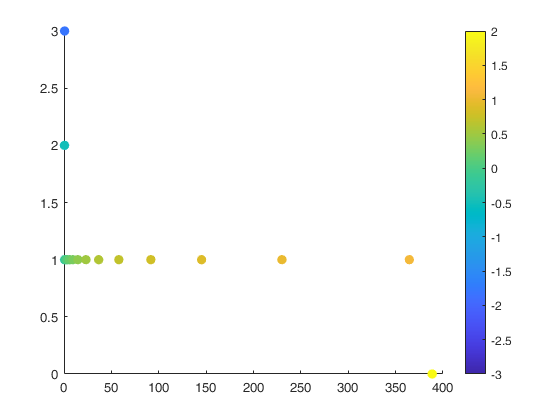

noc = zeros(1,(counter-1));
for i = 1:counter-1
    for j = 1:(M+1)
        if (W(j,i)>0.0007) % 0.0007 je můj určený trashold pro nulový koeficiet v tomto případě
            noc(i) = noc(i) + 1; 
        end
    end    
end
scatter(mse,noc,50,range,'filled')
colorbar